% 2D XRD Analysis
% (XRD of very thin film)

% Unit cell info
a = 4.1; % in Angstrom
a = a*10^-10;

atomPositions = [0 0; 0.5 0.5]; % first x then y nx2 matrix (n number of atoms)

% X-Ray beam 
beamkeV = 8.05; %Enter value in keV
lambda = (H*C)/(beamkeV*(6.2415096471204*10^15)^-1); % m

indx = 10;

planesMaterial = [];
thetaMaterial = [];
intensity = [];
F = [];
dspace = [];
for h = -indx:indx
    for k = -indx:indx
        if k == 0 && h == 0
            continue;
        end
        
        d = dspacing2(h,k,a);

        if lambda/(2*d) <= 1 && lambda/(2*d) >= -1
            theta = asind(lambda/(2*d));

            atoms = zeros(size(atomPositions,1),1);
            for i1 = 1:length(atoms)
                atoms(i1) = exp(2*pi*1i*(h*atomPositions(i1,1)+k*atomPositions(i1,2)));
            end
            f = abs(real(sum(atoms)));
            if f == 0
                continue;
            end

            dspace = [dspace; d];
            F = [F; sum(atoms)*formFactor(4*pi*sind(theta)/(lambda*10^10))];
            planesMaterial = [planesMaterial; h,k];
            thetaMaterial = [thetaMaterial; theta];
            intensity = [intensity; abs(F(end))^2];
        end
    end
end

data = [planesMaterial,2*thetaMaterial,dspace*10^10,intensity];
array2table(data,"VariableNames",{'h', 'k', '2theta [º]','dspace [A]', 'Intensity'})

ans = 44×5 table
    h     k     2theta [º]    dspace [A]    Intensity
    __    __    __________    __________    _________

    -5    -1      146.56       0.80408       862.57  
    -5     1      146.56       0.80408       862.57  
    -4    -2      114.28       0.91679       1050.8  
    -4     0      97.407         1.025       1236.5  
    -4     2      114.28       0.91679       1050.8  
    -3    -3      105.67       0.96638       1135.7  
    -3    -1      72.877        1.2965       1686.4  
    -3     1      72.877        1.2965       1686.4  
    -3     3      105.67       0.96638       1135.7  
    -2    -4      114.28       0.91679       1050.8  
    -2    -2       64.18        1.4496       1915.1  
    -2     0      44.129          2.05       2599.2  
    -2     2       64.18        1.4496       1915.1  
  

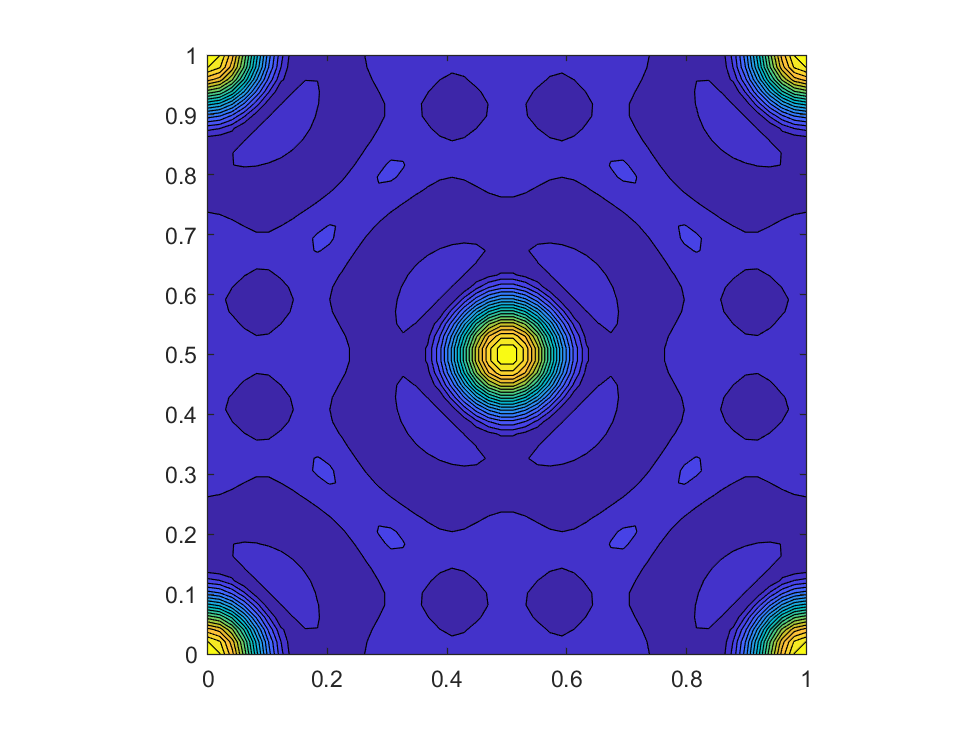

points = 50;

positions = ones([1 points]).*linspace(0,1,points);
P = zeros(points);
for u = 1:points
    for v = 1:points
        for plane = 1:length(planesMaterial)
            P(u,v) = P(u,v)+...
                abs(F(plane))^2*...
                exp(-2*1i*pi*(planesMaterial(plane,1)*positions(u)+planesMaterial(plane,2)*positions(v)));
        end
    end
end

[X,Y] = meshgrid(positions);
contourf(X,Y,abs(P),20);
axis equal;

function spacing = dspacing2(h1,k1,a)
    spacing = sqrt(((h1^2+k1^2)/a^2)^-1);
end

function f = formFactor(g)
    f = 0;
    ax = [13.338 7.1676 5.6158 1.6735]; %Data for Cu
    bx = [3.5828 0.247 11.3966 64.8126];
    cx = 1.191;
    for idx = 1:4
        f = f + ax(idx)*exp(-bx(idx)*(g/(4*pi))^2)+cx;
    end
end